# NSCS 344, Week 1: Matlab concepts

*Every week, in addition to the cognitive science content I will also provide a document that reviews key Matlab concepts that are needed to complete the assignment.*

## Navigating Matlab

Hopefully you managed to get Matlab installed and can launch it on your computer. When it runs you should be presented with a window that looks like this ...

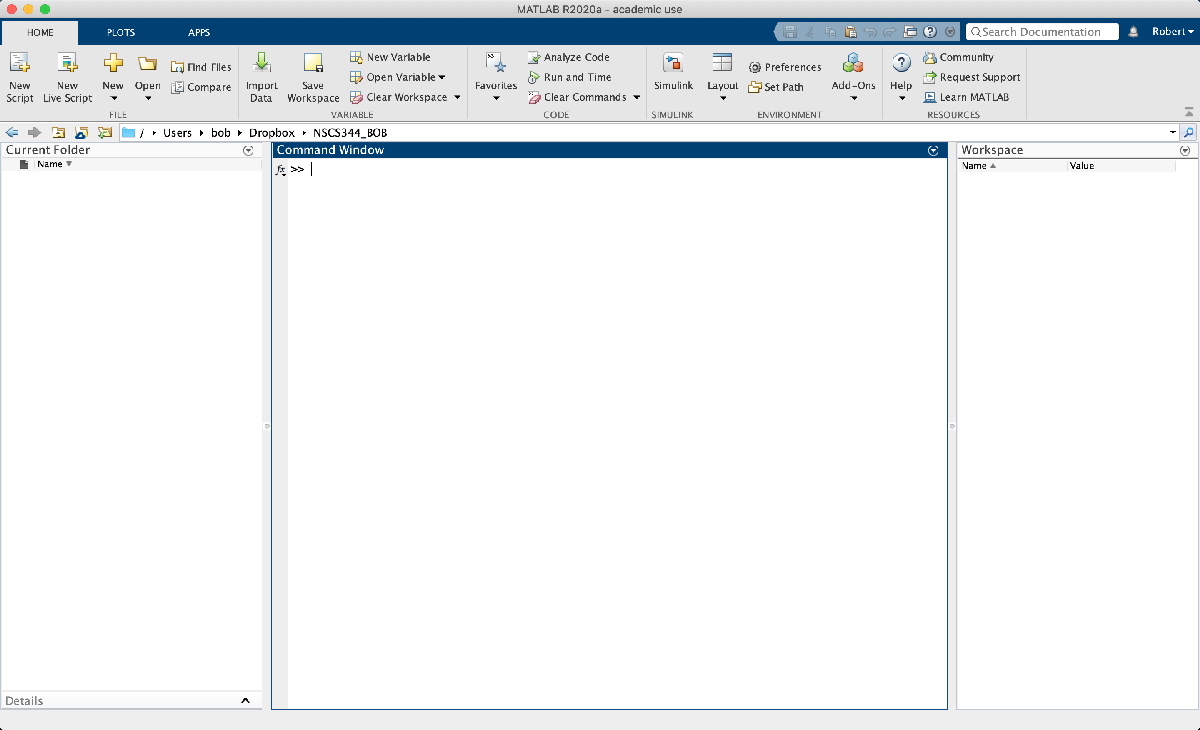

There's a lot going on here, some of which we will never use in this class (especially in the "toolbar" at the top), but let's break down a few things that are essential: the Command Window, the Workspace, the Current Folder, and the (currently invisible) Editor Window. We'll only cover the very basics of these things this week, but you'll see and use these windows over and over again throughout the class.

### The Command Window

The Command Window is the space in the middle of the screen that contains the prompt

As its name suggests, the Command Window is where you can type commands. Don't be fooled, though, it's actually *not* the place (that will be the Editor Window) we'll be typing most of our code, but it's a good place for us to start.

The simplest way to use the Command Window is as an overpowered (and very expensive) calculator. Click your mouse anywhere inside the Command Window and type

1 + 1

and hit enter.  You should see something like this appear inside the Command Window

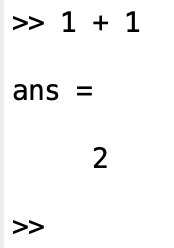

Matlab understood your command and gave you the answer (2).  

You might have noticed that something else changed onscreen too in the Workspace Window on the right ...

### The Workspace 

The Workspace gives you an overview of all the variables that Matlab currently has in memory. If you typed 1 + 1 into the Command Window you should now see something like this in the Workspace  ...

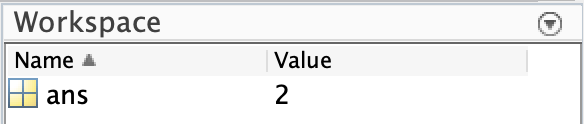

What this is saying is that you have created (or rather, in this case Matlab has created on your behalf) a *variable* called 

that has the value 2.  This was the ans(wer) to the question "1+1".  

Being able to see what's in Matlab's memory at a glance can be super helpful, especially when you are just learning to code. Indeed, many of the coding errors and bugs that we see in this class can be discovered by looking carefully at the Workspace.

We will see this window again when we define variables further down this document ...

### The Current Folder

The current folder tells you the contents of the folder that Matlab is currently looking at. To figure out which directory that is, look at the line just *above *the three windows. 

This says that on my computer I'm in the folder NSCS344_BOB, which is inside the folder Dropbox, which is insider the folder bob, which is inside the folder Users. I don't currently have any files in that folder, so the Current Folder window is empty. That will change!

### The Editor

The most important window of all is actually hidden when you first start up Matlab. This window is the Editor window and it's where you will write your code in a way that can be saved. 

The easiest way to open up the Editor window is to click the "New Script" button at the top left of the toolbar. Doing that should pop open the Editor right in the middle of the screen (pushing the Command Window down to the bottom). This should give you a screen that looks something like this ...

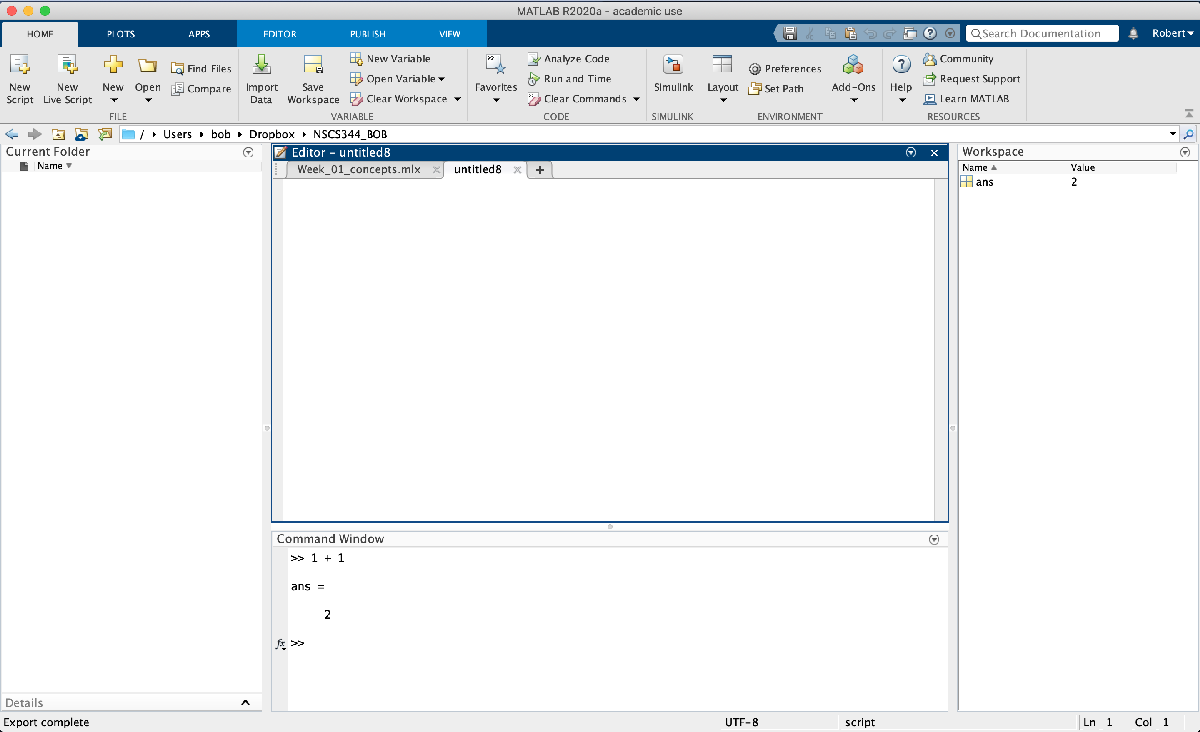

The Editor is basically a word processor (like Microsoft Word or Google Docs) for code. Just like a word processor you can type code (and other text) into the Editor window and then save what you've typed as a file in a specific directory. Also like a word processor there's a kind of "code spelling checker" that puts red and orange squiggles on your code to let you know something might be wrong.

## Writing a script

So now we've created an empty script let's write something in it.  We will start by creating a variable or two before discussing how to clear the workspace.

### Defining variables

A lot of what we are going to be doing with Matlab is creating *variables,* basically just letters that correspond to numbers (and, later on, other things like vectors, matrices, and strings of letters). 

To define a variable try typing 

x = 1

into the *Editor* window (*not *the Command Window) and hit Enter.

You might be surprised that nothing happened (apart from the text appearing) and specifically you might be surprised that nothing changed in the Workspace which, remember, is where our variables should all appear.

The reason why nothing happened is that we haven't actually told Matlab to *run* the command "x = 1". Instead we've simply written some text into a word processor for code. 

To actually run the code, we need to hit the EDITOR tab at the top ...

and then the Run button on the new toolbar that appears when we hit the EDITOR tab ...

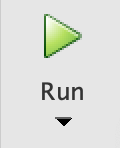

When you do that for the first time you'll get a popup window appear asking you where you want to save your code. This is a good time to navigate to you Dropbox folder (make sure you have installed Dropbox), create your course folder NSCS344_YOURNAME, create a folder inside your course folder called Week01_concepts, and finally save your file there with a name like 

Finally, after you've saved your file it should run and *now* you'll see some changes in the Workspace ...

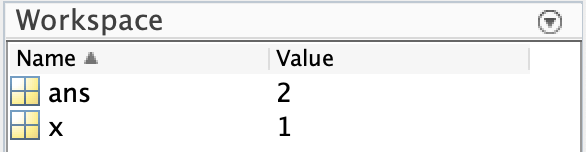

In addition you should see your script pop up as a file in your Current Folder window ...

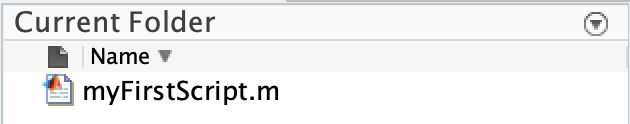

You might also notice this text appear in the Command Window ...

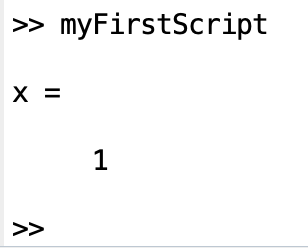

This is saying that you executed your script via the command 

and it gave you an output

If you don't want to see the x = 1 part in the Command Window you can add a semi-colon to the end of the x = 1 line in your code 

x = 1;

*Trust me you won't want to see these kind of outputs once we start making even slightly more complicated code, not least because the outputs SLOW things down A LOT.*

Let's define a few more variables. First, just another number, y

y = 100;

Next let's define variable z to be the product of x and y

z = x * y;

*Note the * denotes multiplication*

When we create variables we are not limited to single letters our variables can be words like

brain = 1;

or

my_brain = 10;

or

myBrainIsAwesome = 100;

However, variables cannot contain spaces, so code like this will lead to errors

In fact, you can kind of see something weird is going on just from the code highlighting turning some of the words pink.  If you run that line you will get an error.

If you run the rest of the code though you should be good and your Workspace should look like this ...

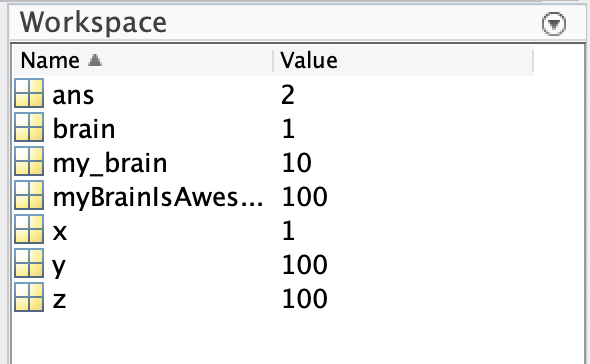

### Clearing the Workspace

Now, if you ran the code up to here you should have a pretty busy Workspace with lots of variables in it. Like all workspaces, problems can arise if the Matlab Workspace gets too cluttered (you'll almost certainly experience this for yourself later on in the course). So a critical part of most scripts - especially when you first run it - is *clearing* the Workspace. This is easy to do, just type

clear

Into the Command Window and you will see all of your variables disappear. 

To automate this, I (almost) always put a clear command at the start of my scripts. There are some exceptions to this rule, but they are rare enough that you will most likely never meet them in this class.

## For loops

One of the reasons computers are so useful is that they are great at doing the same thing over and over again. To take advantage of this ability in Matlab we use "for" loops.

Here's an example of one of the simplest for loops you could write, along with the output you'd see in the Command Window (with slightly cleaner formating)

for i = 1:10
    i
end

Even with this simple example there's a lot going on, so let's break it down.  First, you invoke the for loop using the magic word 

You can tell that "for" is a special word for Matlab because the font color automatically turns blue if you type it into the Editor.

The for is matched with the equally special word 

which ends the for loop. 

All the lines of code between the line containing the "for" and the line containing the "end" are the code that is going to be repeated. In our example there's only one line

which just displays i in the Command Window.

Finally, there's the "i = 1:10" bit.  I always read this (when combined with the for) as

"for $i$ equals 1 to 10"

which means we make a variable $i$ and start it off with value 1.  Each time through the loop we increase it by 1 until we get to 10.

Using this, we can create a for loop twist on the classic [Hello World!](https://en.wikipedia.org/wiki/%22Hello,_World!%22_program) program

for i = 1:10
    disp('Hello World!')
end

Where the disp function displays the text which is inside it. 

Finally, note the line inside the for loop are indented.  This is good programming form because it lets you easily identify what code is in the for loop. Matlab tries to do this indentation automatically. However, it doesn't always work (especially if you do a bunch of copy-pasting of your code) and a quick way to clean things up is this pair of keys on a Mac

Or on Windows

It's remarkable how many bugs in your code you can pick up with this pair of key presses.  Your code this week probably won't get complex enough to need it, but remember this for later on if you can!

## If statements

If statements allow us to change what Matlab does depending on some condition. For example, if I want to only have it display a message when a variable $V$ is 2, I could write something like this

if V == 2
    disp('Hello World!')
end

The double equals (i.e. the ==) is used to check whether $V$ is 2 or not.  We can't use a single equals because Matlab reserves the single equals to define a variable.

So when I write

V = 1;

I set the value of $V$ to be 1. But when I write

V == 1;

I am checking whether $V$ is 1 or not.  

*Note that the output of this comparison is what's called a Boolean or Logical number - it's either 0 (if *$V$* does not equal 1) or 1 (if *$V$* does equal 1).*

If I would like to execute different code if $V$ is not 2, then I can use the "else" keyword

if V == 2
    disp("Hello World!")
else
    disp("Goodbye!")
end

You can almost read this in English as

*If V is 2 display "Hello World!" else (if V is not 2) display "Goodbye!"*

Finally, if you want to add something specifial for V is 3 too, then you can use the  "elseif" keyword

if V == 2
    disp("Hello World!")
elseif V == 3
    disp("Hello Mars!")
else
    disp("Goodbye!")
end

So ... **If** this all makes sense, please go on to try the Assignment, **elseif **it doesn't **for **all of your questions, reach out to one of the Instructors (**end**)! That brings this initial Concepts document to an **end**.